In this file, we will try to find a way to plot "arrows" when graphing the network.

clear all
close all

load TempNet.mat
obj = net.platoons(1)

obj =   Platoon with properties:

     platoonIndex: 1
    numOfVehicles: 4
         vehicles: [1×4 Vehicle]
         topology: [1×1 Topology]
         graphics: [30.4893 31.4893 32.4893 33.4893 34.4893 35.4893 36.4893]


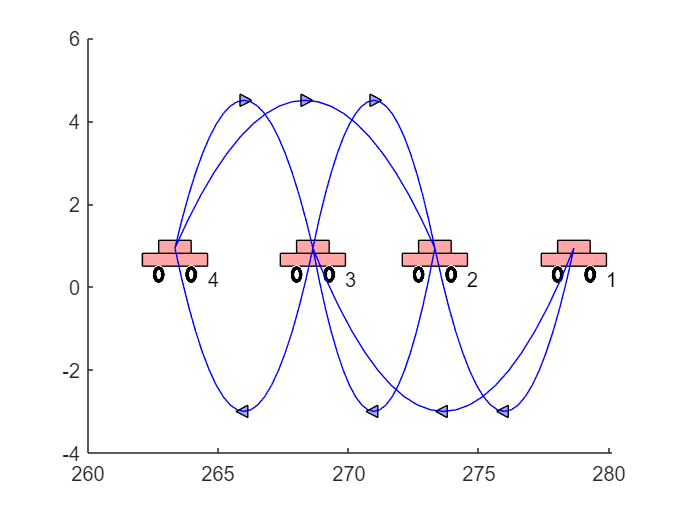


figure(1); hold on;

for i = 1:1:obj.numOfVehicles
    obj.vehicles(i).drawVehicle(1);
end

numOfLinks = length(obj.topology.startNodes);
for i = 1:1:numOfLinks
    startVehicleIndex = obj.topology.startNodes(i);
    endVehicleIndex = obj.topology.endNodes(i);
    
    startPos = obj.vehicles(startVehicleIndex).states(1) - obj.vehicles(startVehicleIndex).vehicleParameters(2)/2;
    endPos = obj.vehicles(endVehicleIndex).states(1) - obj.vehicles(endVehicleIndex).vehicleParameters(2)/2;
    midPos = (startPos + endPos)/2;
    midPointHeight = -3*sign(startPos-endPos)+0.0*abs(startPos-endPos)+1.5*(startPos<endPos);
    
    startPosY = obj.vehicles(startVehicleIndex).vehicleParameters(2)*3/8;
    endPosY = obj.vehicles(endVehicleIndex).vehicleParameters(2)*3/8;
%     obj.graphics(i) = plot([startPos,midPos,endPos],[startPosY,midPointHeight,endPosY],'-b');

    % Plotting the Spline
    x = [startPos,midPos,endPos];
    y = [startPosY,midPointHeight,endPosY];
    stepSize = (endPos-startPos)/20; 
    xx = startPos:stepSize:endPos;
    yy = spline(x,y,xx);
    obj.graphics(i) = plot(xx,yy,'-b');

    % Plotting the arrowHead (polyshape)
    polyPosX = midPos;
    polyPosY = midPointHeight;
    polySize = 0.3;
    polyVertX = [-0.5,1,-0.5];
    polyVertY = [0.5,0,-0.5];
    if polyPosY < 0
        polyVertX = -polyVertX;
    end
    arrowHead = polyshape(polyPosX+polySize*polyVertX,polyPosY+polySize*polyVertY);
    plot(arrowHead,'EdgeColor','k','FaceColor','b')
end

Polyshape and Spline functions testing:

figure(2)
x = [startPos,midPos,endPos]

x =   263.3372  265.9843  268.6313


y = [startPosY,midPointHeight,endPosY]

y =     0.9375    4.5000    0.9375


stepSize = (endPos-startPos)/20 

stepSize = 0.2647

xx = startPos:stepSize:endPos

xx =   263.3372  263.6019  263.8666  264.1313  264.3960  264.6607  264.9254  265.1901  265.4548  265.7196  265.9843  266.2490  266.5137  266.7784  267.0431  267.3078  267.5725  267.8372  268.1019  268.3666  268.6313


yy = spline(x,y,xx)

yy =     0.9375    1.6144    2.2200    2.7544    3.2175    3.6094    3.9300    4.1794    4.3575    4.4644    4.5000    4.4644    4.3575    4.1794    3.9300    3.6094    3.2175    2.7544    2.2200    1.6144    0.9375


plot(x,y,'o',xx,yy,'-b')

hold on
polySize = 0.3

polySize = 0.3000

polyPosX = midPos

polyPosX = 265.9843

polyPosY = midPointHeight

polyPosY = 4.5000

polyVertX = [-0.5,1,-0.5]

polyVertX =    -0.5000    1.0000   -0.5000


polyVertY = [0.5,0,-0.5]

polyVertY =     0.5000         0   -0.5000


if polyPosY < 0
    polyVertX = -polyVertX
end
p = polyshape(polyPosX+polySize*polyVertX,polyPosY+polySize*polyVertY)

p =   polyshape with properties:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0


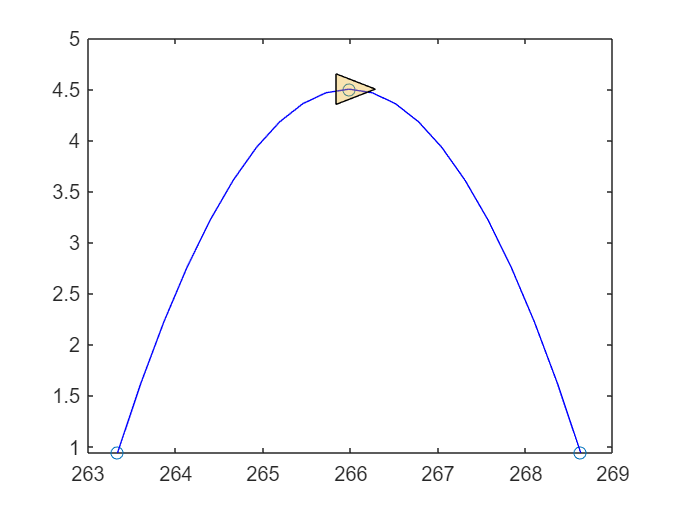

plot(p)